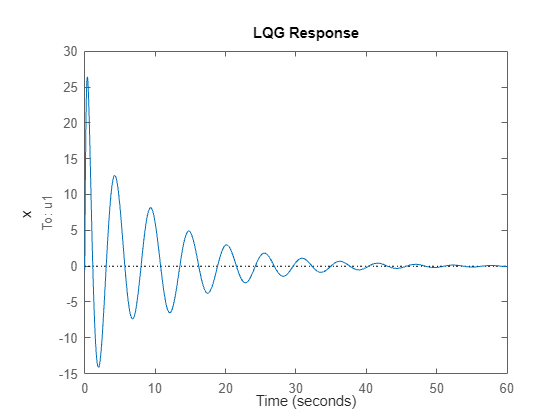

clc;
clear;
close all;

% Given system values
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.81;

% Defining the State Equation matrices
A=[0 1 0 0 0 0;
    0 0 (-m1*g/M) 0 (-m2*g/M) 0;
    0 0 0 1 0 0;
    0 0 ((-g*(M+m1))/(l1*M)) 0 ((-g*m2)/(l1*M)) 0;
    0 0 0 0 0 1;
    0 0 ((-g*m1)/(l2*M)) 0 ((-g*(M+m2))/(l2*M)) 0];

B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
C=eye(6);
D=0;

% Assigning the Q and R cost function values to check the performance of
% the controller system
Q=[10 0 0 0 0 0;
    0 10 0 0 0 0 ;
    0 0 200 0 0 0;
    0 0 0 200 0 0;
    0 0 0 0 200 0;
    0 0 0 0 0 200];

R=0.001;

%Output Vectors 
x_only=[1 0 0 0 0 0];
x_theta2=[1 0 0 0 0 0;
          0 0 0 0 1 0];
x_theta1_theta2=[1 0 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 0 1 0];

%Process Noise
PNC= eye(7);

%Measurement Noise
n1=wgn(6,1,5);
n2=wgn(1,1,5);
MNC=[n1;n2]*[n1' n2'];

%Defining the state state space model of the system
system1=ss(A,B,x_only,D);

%LQG Controller for the system
lqgss1=lqg(system1,PNC,MNC);

%Setting Initial Conditions
X_Initial=[1;0;deg2rad(10);0;deg2rad(20);0];

%Plot the response of the system to the initial conditions
figure
initial(lqgss1,X_Initial)
title('LQG Response')
xlabel('Time')
ylabel('x')

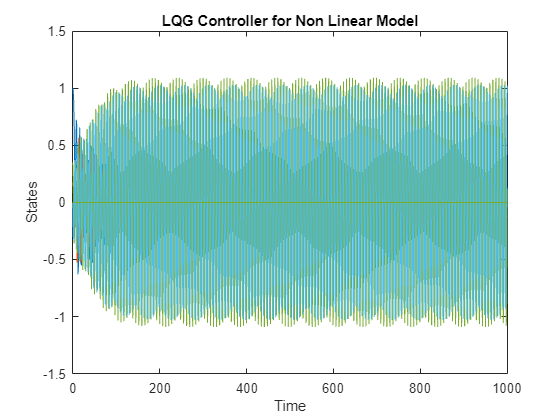


%Simulating the Non Linear System
X_Initial1=[1,0,deg2rad(10),0,deg2rad(20),0,0,0,0,0,0,0];%Setting Initial Conditions for Non linear system
tspan=0:1:1000;%Time span for simulating the non linear system
[t,y]=ode45(@lqg_system,tspan,X_Initial1);

%Plotting the response of the Non Linear System
figure
plot(t,y)
title('LQG Controller for Non Linear Model')
xlabel('Time')
ylabel('States')

function y = lqg_system(ts,Init)
    % Given system values
    M = 1000;
    m1 = 100;
    m2 = 100;
    l1 = 20;
    l2 = 10;
    g = 9.81;

    theta1=Init(3);
    theta1_dot=Init(4);
    theta2=Init(5);
    theta2_dot=Init(6);

    % Define system matrices
    A=[0 1 0 0 0 0;
        0 0 (-m1*g/M) 0 (-m2*g/M) 0;
        0 0 0 1 0 0;
        0 0 ((-g*(M+m1))/(l1*M)) 0 ((-g*m2)/(l1*M)) 0;
        0 0 0 0 0 1;
        0 0 ((-g*m1)/(l2*M)) 0 ((-g*(M+m2))/(l2*M)) 0];
    
    B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
    %Assume Values of Q and R (cost functions)such that it stabilizes the system
    Q=[10 0 0 0 0 0;
        0 10 0 0 0 0 ;
        0 0 200 0 0 0;
        0 0 0 200 0 0;
        0 0 0 0 200 0;
        0 0 0 0 0 200];
    
    R=0.001;
    
    %Considering x(t) as the output vector
    x_only=[1 0 0 0 0 0;0 0 0 0 0 0;0 0 0 0 0 0;0 0 0 0 0 0;0 0 0 0 0 0;0 0 0 0 0 0];
    
    %Obtaining the Gain Matrix for simulating the system
    [K,~,~]=lqr(A,B,Q,R);
    F=-K*Init(1:6);
    
    %States of the system
    y=zeros(12,1);
    x_ddot=(F-(m1*l1*(theta1_dot)*(theta1_dot)*sin(theta1))+(m2*g*cos(theta2)*sin(theta2))-(m1*g*cos(theta1)*sin(theta1))-(m2*l2*theta2_dot*theta2_dot*sin(theta2)))/(M+m1+m2-(m1*cos(theta1)*cos(theta1))-(m1*cos(theta1)*cos(theta1)));
    theta1_ddot = (x_ddot*cos(theta1)-g*sin(theta1))/l1;
    theta2_ddot = (x_ddot*cos(theta2)-g*sin(theta2))/l2;
    
    %Defining Process noise 
    PN=eye(6);
    
    %Gain Matrix of the system obtained through a LQR Controller
    K_gain= lqr(A',x_only',PN,1);

    %State Estimates
    hat = (A-K_gain*x_only)*Init(7:12);

    % State Space Representation 
    y(1) = Init(2);
    y(2) = x_ddot;
    y(3) = Init(4);
    y(4) = theta1_ddot;
    y(5) = Init(6);
    y(6) = theta2_ddot;
    y(7) = hat(1);
    y(8) = hat(2);
    y(9) = hat(3);
    y(10) = hat(4);
    y(11) = hat(5);
    y(12) = hat(6);

end

